DENTIFICACIÓN DEL SISTEMA: RESPUESTA AL ESCALÓN Y PRBS

- Procesa datos de simulación (escalón)

- Procesa datos medidos del escalón real

- Procesa datos medidos del ensayo PRBS

- Filtra, normaliza y genera iddata para System Identification

## DATOS DE SIMULACIÓN DEL ESCALÓN


datos_sim = readmatrix('datos_escalon_simulacion.DAT');

t_sim = datos_sim(:,1) - 3.006216984;
y_sim = datos_sim(:,2) - min(datos_sim(:,2));   % salida normalizada
u_sim = datos_sim(:,3) * (3/5);                 % reescala la entrada

Ts_sim = mean(diff(t_sim));

% --- Filtrado temporal por remuestreo manual ---
t_inicio = 0;
t_fin    = 6;
dt       = 0.001;

Npts = floor((t_fin - t_inicio)/dt);
i = 1;

Tt_sim = zeros(1, Npts);
u_sim_filt = zeros(1, Npts);
y_sim_filt = zeros(1, Npts);

for k = 1:Npts
    while (i < length(t_sim)) && (t_sim(i) < t_inicio + k*dt)
        i = i + 1;
    end
    Tt_sim(k) = (k-1)*dt;
    u_sim_filt(k) = u_sim(i);
    y_sim_filt(k) = y_sim(i);
end

u_sim_filt(1) = 0;

% Defino el objeto  para el system identification
data_sim_escalon = iddata(y_sim_filt', u_sim_filt', dt);



## DATOS MEDIDOS DEL ESCALÓN REAL


datos_escalon = readtable('datos_escalon_medido.CSV');

t_escalon = datos_escalon.Var4(4:end) + 3; % corrige offset
T_escalon = mean(diff(t_escalon));

y_escalon = datos_escalon.Var5(4:end);
y_escalon = y_escalon - mean(y_escalon(1:6000));   % elimina offset

% --- Filtro pasabajos ---
fs = 1/T_escalon;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

y_med_filt = filter(b_med, a_med, y_escalon);

% --- Procesamiento de la entrada ---
u_escalon = datos_escalon.Var6(4:end);
u_escalon(u_escalon < 4) = 0;
u_escalon(u_escalon >= 4) = 3;

data_med_escalon = iddata(y_med_filt, u_escalon, T_escalon);

% Transferencia ideal ejemplo
s = tf('s');
G_ideal = 1/(s*0.1 + 1)^6;



## DATOS MEDIDOS PRBS REAL


datos_prbs = readtable('datos_prbs_medido.CSV');

T_prbs = 1/200;

% --- Salida ---
y_prbs = datos_prbs.Var2;
y_prbs = (y_prbs - 1000) / 3000;

% recorta negativos
y_prbs(y_prbs < 0) = 0;

% --- Entrada ---
u_prbs = datos_prbs.Var1;
u_prbs(u_prbs < 2500) = 0;
u_prbs(u_prbs >= 2500) = 1;

data_med_prbs = iddata(y_prbs, u_prbs, T_prbs);


## APROXIMACIÓN FOPDT 

Basado en el modelo obtenido en el ensayo de PRBS y del escalón, se obtuvo:


$$\begin{array}{l}
G_{\textrm{FOPDT}} =\frac{K_p e^{-\textrm{Ls}} }{1+\textrm{Ts}}=\frac{\left(0\ldotp 98257\right)e^{-\left(0\ldotp 34639\right)s} }{1+\left(0\ldotp 50484\right)s}\\
\\
T=0\ldotp 50484\\
L=0\ldotp 34639\\
K_{p\;} =0\ldotp 98257
\end{array}$$


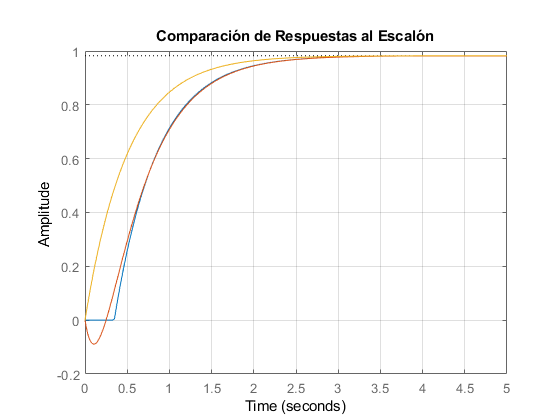

% Defino el modelo FOPDT y los parámetros del PID
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 
G_aprox = G_sin_retardo*(1-(s*L/2))/(1+(s*L/2));  %  Aproximado por Padé

% grafico

figure;
h = stepplot(G_fopdt, G_aprox, G_sin_retardo);
grid on;
title("Comparación de Respuestas al Escalón");

## DISEÑO DEL PID (asignacion de polos)

Basado el el modelo aproximado de primer orden, se diseña el PID


$$G_{\textrm{aprox}} \;\;=\;\frac{\left(0\ldotp 98662\right)\left(1-\frac{\left(\textrm{s0}\ldotp 15\right)}{2}\right)}{\left(1+\left(0\ldotp 75618\right)s\right)\left(1+\frac{s\left(0\ldotp 15\right)}{2}\right)}$$



$$PID_{SP}(s) = 
\frac{k_c (1 + T_I s)(1 + T_D s)}
{T_I s (1 + \alpha T_D s)},$$


% Defino parametros del modelo
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 

% Defino parametros del PID

T_D = 0.5*L;
T_I = T;
alfa = 0.6;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2

T_0 = 0.2736

k_c  = 2*T/(K_p*(L  + 4*T_0));

% Calculo transferencias del PID

G_aprox = G_sin_retardo * (1 - (L/2)*s) / (1 + (L/2)*s);
PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s))

PID =
 
  0.06236 s^2 + 0.4836 s + 0.7132
  -------------------------------
      0.05246 s^2 + 0.5048 s
 
Continuous-time transfer function.



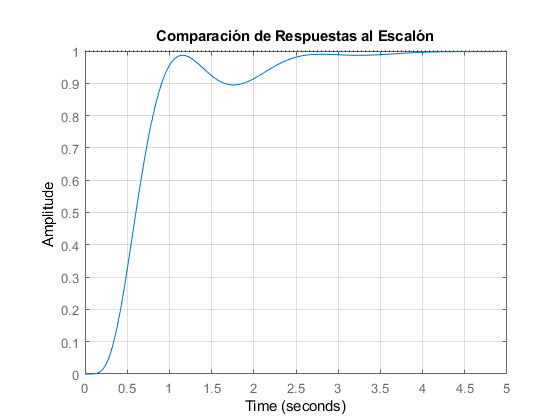


Taprox = feedback(G_aprox*PID, 1);
Treal = feedback(G_fopdt*PID, 1);

% planta modelada con system Identification
xg = [5.671618964260603e+05];
yg = 1.0e+05 *[0.000010000000000 0.000582840996742 0.012844454912094 0.162297100468771 1.087898782652298 3.983829952470905 5.775054615523315];

G_posta = tf(xg, yg);

Tposta = feedback(G_posta*PID, 1);

Tideal = feedback(G_ideal*PID,1);
% grafico

figure;
h = stepplot(Tposta);
grid on;
title("Comparación de Respuestas al Escalón");

## Discretizacion de la planta

% Defino parametros del modelo
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

Tm = 0.030;

% Defino parametros del PID

T_D = 0.5*L

T_D = 0.1732

T_I = T

T_I = 0.5048

alfa = 0.6;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2

T_0 = 0.2736

k_c  = 2*T/(K_p*(L  + 4*T_0))

k_c = 0.7132


PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s));

PIDz = c2d(PID, Tm, 'zoh')

PIDz =
 
  1.189 z^2 - 2.132 z + 0.9535
  ----------------------------
     z^2 - 1.749 z + 0.7492
 
Sample time: 0.03 seconds
Discrete-time transfer function.



[x, y]=tfdata(PIDz, 'v');



## Robustes para la familia de modelos

%--------------------------------------------
% Familia de modelos de la planta G

t1 = ureal('t1', 0.1, 'Range', [0.08 0.12]);
t2 = ureal('t2', 0.1, 'Range', [0.08 0.12]);
t3 = ureal('t3', 0.1, 'Range', [0.08 0.12]);
t4 = ureal('t4', 0.1, 'Range', [0.08 0.12]);
t5 = ureal('t5', 0.1, 'Range', [0.08 0.12]);
t6 = ureal('t6', 0.1, 'Range', [0.08 0.12]);

s = tf('s');

G = 1 / ((s*t1+1)*(s*t2+1)*(s*t3+1)*(s*t4+1)*(s*t5+1)*(s*t6+1))

G =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 13 states.
  The model uncertainty consists of the following blocks:
    t1: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t2: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t3: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t4: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t5: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences
    t6: Uncertain real, nominal = 0.1, range = [0.08,0.12], 1 occurrences

Type "G.NominalValue" to see the nominal value, "get(G)" to see all properties, and "G.Uncertainty" to interact with the uncertain elements.




%---------------------------------------------
% Modelo de la planta Fopdt

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

G_fopdt = (K_p)/(1+s*T);

%----------------------------------------------
% PID

T_D = 0.5*L;
T_I = T;
alfa = 0.6;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2

T_0 = 0.2736

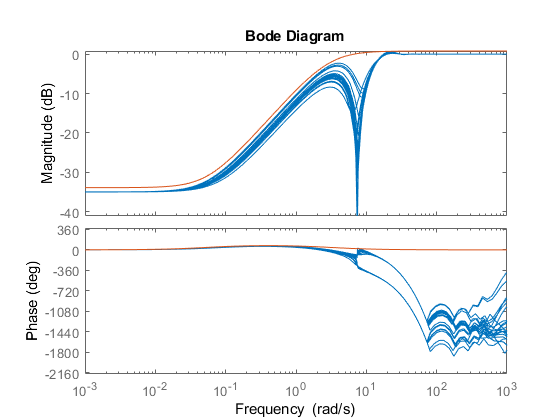

k_c  = 2*T/(K_p*(L  + 4*T_0));

PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s));

%----------------------------------------------
% Modelo de la planta de 6 polos
xg = [5.671618964260603e+05];
yg = 1.0e+05 *[0.000010000000000 0.000582840996742 0.012844454912094 0.162297100468771 1.087898782652298 3.983829952470905 5.775054615523315];

G_posta = tf(xg, yg);

%----------------------------------------------
% funciones de tranferencia

Tfopdt = feedback(G_fopdt*PID, 1);

Tposta = feedback(G_posta*PID, 1);

%----------------------------------------------
% Robustes para modelo nominal fopdt

w = 1 + s - s;
w.InputDelay = L; 
w = G/G_fopdt - w;

W_foppdt = 1.097*(s + 0.055 )/(s + 3);

bode(w, W_foppdt)

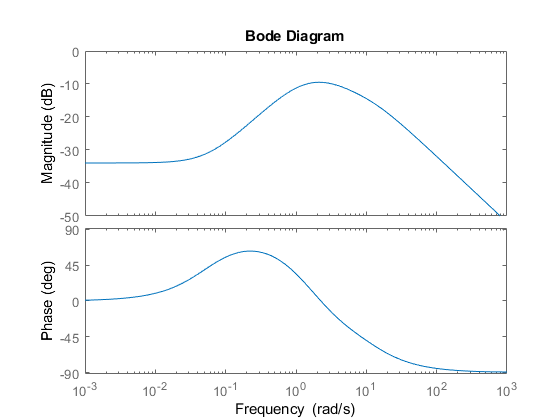

bode(Tfopdt*W_foppdt)

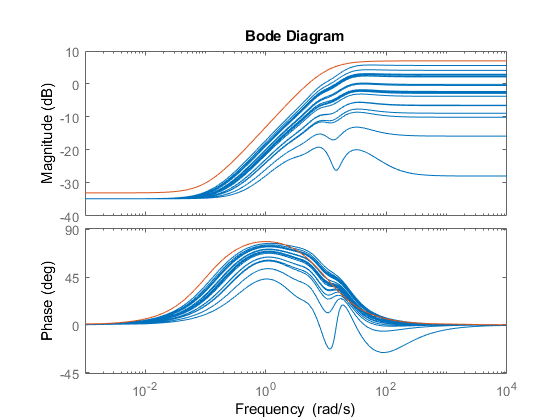


%----------------------------------------------
% Robustes para modelo nominal de 6 polos


ww = G/G_posta -1;

W_posta = 2.24*(s + 0.1 )/(s + 10);

bode(ww, W_posta)

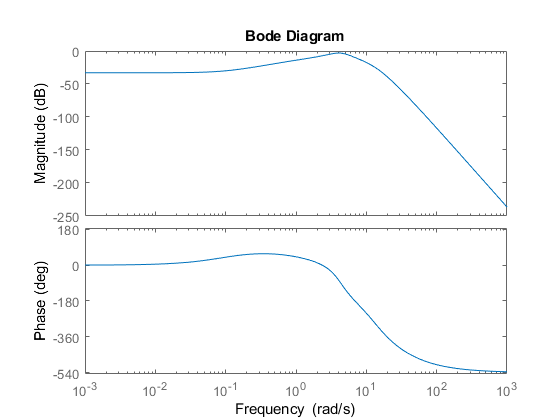

bode(Tposta*W_posta)


%----------------------------------------------


## Datos del pid

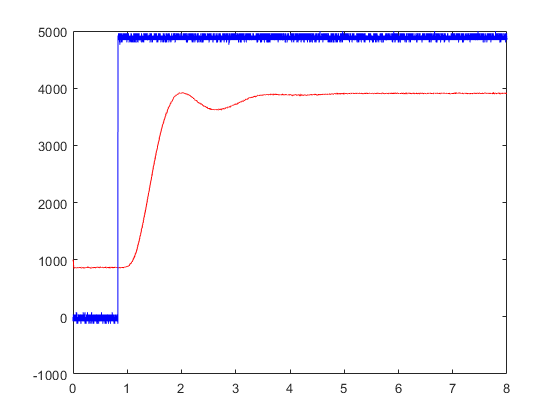

% cambio de referencia
datos_respuesta_cambio_referencia = readtable('r.CSV');


referencia = datos_respuesta_cambio_referencia.Var1;
datos = datos_respuesta_cambio_referencia.Var2;
datos = datos -1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

datos = filter(b_med, a_med, datos)+1000;

tiempo = (0:0.00025:0.00025*(size(datos)-1));
plot(tiempo, datos,'r',tiempo,referencia, 'b');


mean(datos(24000:end))

ans = 3.9091e+03

mean(datos(500:3500))

ans = 862.8345


3.364-0.8285

ans = 2.5355

1.142-0.8285

ans = 0.3135

3.364-1.169

ans = 2.1950

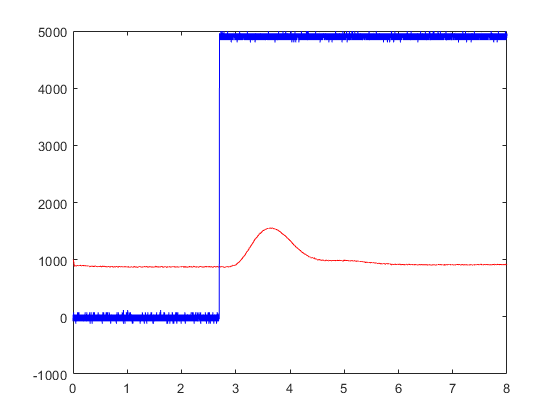


% respuesta a la perturbaciones
datos_respuesta_perturbaciones = readtable('p.CSV');


perturbacion = datos_respuesta_perturbaciones.Var1;
datos_p = datos_respuesta_perturbaciones.Var2;
datos_p = datos_p -1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 30;
[b_med, a_med] = butter(4, fc/(fs/2));

datos_p = filter(b_med, a_med, datos_p)+1000;

tiempo_p = (0:0.00025:0.00025*(size(datos_p)-1));
plot(tiempo_p, datos_p,'r',tiempo_p,perturbacion, 'b');


mean(datos_p(24000:end))

ans = 912.0297

mean(datos_p(4000:10000)) + 50

ans = 924.0952


3.014 - 2.699

ans = 0.3150

5.85 - 3.014

ans = 2.8360

## Simulacion/real escalon

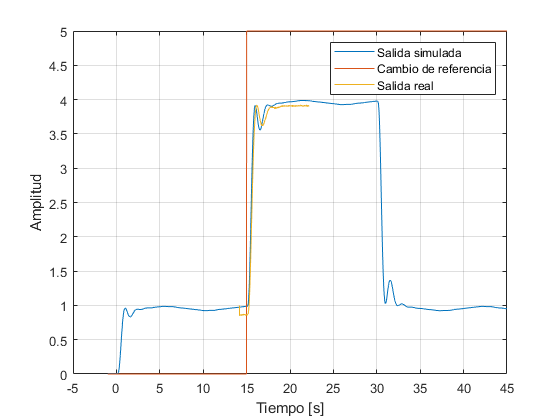

% Datos simulados
datos_sim_ref = readmatrix('cambio_de_referencia_simulacion.DAT');

tiempo_sim = datos_sim_ref(:,1);
salida_sim = datos_sim_ref(:,2);
escalon_sim = datos_sim_ref(:,3);

% Datos del osciloscopio
datos_respuesta_cambio_referencia = readtable('r.CSV');

referencia = datos_respuesta_cambio_referencia.Var1;
datos = datos_respuesta_cambio_referencia.Var2;
datos = datos -1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

datos = filter(b_med, a_med, datos)+1000;

tiempo = (0:0.00025:0.00025*(size(datos)-1));

% desplazar en el tiempo para sincronizar los escalones
i=1;
while referencia(i)<3000
    nr = i;
    i = i + 1;
end

i=1;
while escalon_sim(i)<3
    ne = i;
    i = i + 1;
end

tiempo = tiempo + tiempo_sim(ne) -tiempo(nr);

% grafico
plot(tiempo_sim, salida_sim, ...
     tiempo_sim, escalon_sim, ...
     tiempo, datos/1000);

xlabel('Tiempo [s]');
ylabel('Amplitud');

legend('Salida simulada', ...
       'Cambio de referencia', ...
       'Salida real');
grid on;

## Simulacion/real perturbacion

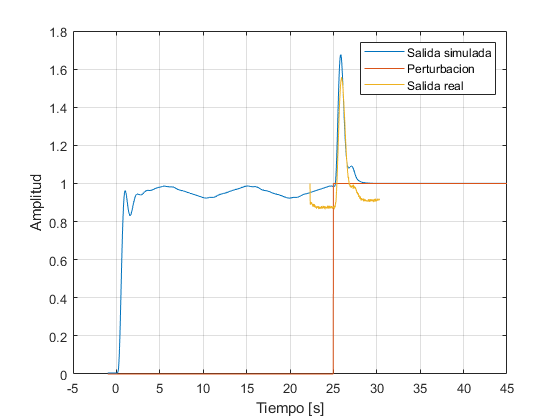

% Datos simulados
datos_sim_per = readmatrix('perturbacion_simulacion.DAT');

tiempo_p_sim = datos_sim_per(:,1);
salida_p_sim = datos_sim_per(:,2);
perturbacion_sim = datos_sim_per(:,3);

% Datos del osciloscopio
datos_respuesta_perturbaciones = readtable('p.CSV');


perturbacion = datos_respuesta_perturbaciones.Var1;
datos_p = datos_respuesta_perturbaciones.Var2;
datos_p = datos_p -1000;
% --- Filtro pasabajos ---
fs = 4000;
fc = 30;
[b_med, a_med] = butter(4, fc/(fs/2));

datos_p = filter(b_med, a_med, datos_p)+1000;

tiempo_p = (0:0.00025:0.00025*(size(datos_p)-1));


% desplazar en el tiempo para sincronizar los escalones
i=1;
while perturbacion(i)<3000
    nr = i;
    i = i + 1;
end

i=1;
while perturbacion_sim(i)<3
    ne = i;
    i = i + 1;
end

tiempo_p = tiempo_p + tiempo_p_sim(ne) -tiempo_p(nr);

% grafico
plot(tiempo_p_sim, salida_p_sim, ...
     tiempo_p_sim, perturbacion_sim/5, ...
     tiempo_p, datos_p/1000);

xlabel('Tiempo [s]');
ylabel('Amplitud');

legend('Salida simulada', ...
       'Perturbacion', ...
       'Salida real');
grid on;




17.09 - 15

ans = 2.0900

17.09 - 15.26

ans = 1.8300

15.26 - 15

ans = 0.2600



27.49 -25.3

ans = 2.1900

25.3 - 25

ans = 0.3000